Interface de texto para PVI

Autor:

  - Arménio Correia  .: armenioc@isec.pt

  - Ana Rita Conceição Pessoa - 2023112690 

  - João Francisco de Matos Claro - 2023112690 

Data : 13/03/2024

clear
% syms y(t)

strF="y+exp(3*t)";
%f=@(t,y) eval(vectorize(strF));
f=str2func(vectorize(strcat('@(t,y)', " ", strF)));
a = 0;
b = 1.5;
if ~(isscalar(b) && b > a)
    disp("Introduza um b > a");
end
n = 3;
if ~(isscalar(n) && n==floor(n) && n > 0)
    disp("Introduza um valor de n correto");
end
y0 = 2;

if(false)
    [t, y]=NEuler(f,a,b,n,y0);
    mostraAproximacoes("Euler",y);
    mostraGrafico("Euler", y, t);
end
if(true)
    [t, y]=NEulerMelhorado(f,a,b,n,y0);
    mostraAproximacoes("Euler Melhorado",y);
    mostraGrafico("Euler Melhorado", y, t);
end


Aproximações obtidas Euler Melhorado:
                   y               
    _______________________________

    2       3.5    7.4908    21.279



if(true)
    [t, y]=RK2(f,a,b,n,y0);
    mostraAproximacoes("RK2",y);
    mostraGrafico("RK2", y, t);
end


Aproximações obtidas RK2:
                   y               
    _______________________________

    2    4.7454    14.413    53.458



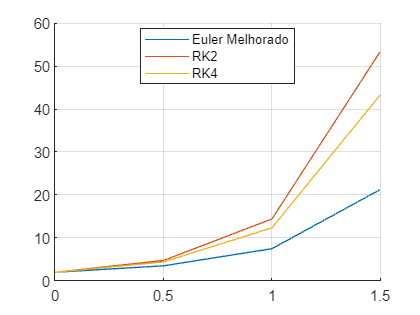


Aproximações obtidas RK4:
                   y               
    _______________________________

    2    4.4043    12.348     43.36



if(true)
    [t, y]=RK4(f,a,b,n,y0);
    mostraAproximacoes("RK4",y);
    mostraGrafico("RK4", y, t);
end

if(false)
    [tode, y]=ode45(f, [a b], y0);
    mostraAproximacoes("ode45", y);
    mostraGrafico("ode45", y, tode);
    fprintf('\nPontos de aproximação da ode45\n');
    disp(table(tode));
end
if(false)
    [t, y]=AdamBashford(f,a,b,n,y0);
    mostraAproximacoes("Adams-Bashfords",y);
    mostraGrafico("Adams-Bashfords", y, t);
end
if(false)
    [t, y]=sExata(f,a,b,n,y0);
    mostraAproximacoes("Exata",y);
    mostraGrafico("Exata", y, t);
end
fprintf('\nPontos de aproximação \n');


Pontos de aproximação 


disp(table(t));

              t           
    ______________________

    0    0.5      1    1.5



clf reset;

function mostraGrafico(metodo, y, t)

% fprintf('Deseja visualizar o grafico? (y,n)\n');
% ch=input('Opção: ', 's');
% if strcmp(ch,'y')
    hold on
    plot (t,y, 'DisplayName', metodo);
    legend('location', 'best');
    hold off
    grid on
% else
%     fprintf('\nIntroduza y ou n\n');
% end
end

function mostraAproximacoes(metodo, y)
fprintf('\nAproximações obtidas ' + metodo + ":\n");
disp(table(y));
end
